clear

profile on

% Symbolic Math Toolboxを使用して変数を宣言
syms g A_d f_d

% iの最大値を指定
n = 30;

% 各変数のリストを作成
r_list = [];
rho_list = [];
l_R_list = [];
l_L_list = [];
k_theta_list = [];
c_theta_list = [];

% 動的に変数を定義
for i = 1:n
    eval(['syms r_' num2str(i)])
    eval(['syms rho_' num2str(i)])
    eval(['syms l_R_' num2str(i)])
    eval(['syms l_L_' num2str(i)])

    eval(['syms k_theta_' num2str(i)])
    eval(['syms c_theta_' num2str(i)])

    % リストに追加
    r_list = [r_list; eval(['r_' num2str(i)])];
    rho_list = [rho_list; eval(['rho_' num2str(i)])];
    l_R_list = [l_R_list; eval(['l_R_' num2str(i)])];
    l_L_list = [l_L_list; eval(['l_L_' num2str(i)])];
    k_theta_list = [k_theta_list; eval(['k_theta_' num2str(i)])];
    c_theta_list = [c_theta_list; eval(['c_theta_' num2str(i)])];


    eval(['syms x_' num2str(i) '(t) y_' num2str(i) '(t) theta_' num2str(i) '(t)'])
    eval(['syms x_dot_' num2str(i) '(t) y_dot_' num2str(i) '(t) theta_dot_' num2str(i) '(t)'])
    eval(['syms x_dot_dot_' num2str(i) '(t) y_dot_dot_' num2str(i) '(t) theta_dot_dot_' num2str(i) '(t)'])

    eval(['syms x_depend_' num2str(i) ' y_depend_' num2str(i) ' theta_depend_' num2str(i)])
    eval(['syms x_depend_dot_' num2str(i) ' y_depend_dot_' num2str(i) ' theta_depend_dot_' num2str(i)])
    eval(['syms x_depend_dot_dot_' num2str(i) ' y_depend_dot_dot_' num2str(i) ' theta_depend_dot_dot_' num2str(i)])
end

% 動的にベクトルを構築
q = cell(n, 1);
q_dot = cell(n, 1);
q_dot_dot = cell(n, 1);

for i = 1:n
    q{i} = eval(['[x_' num2str(i) '; y_' num2str(i) '; theta_' num2str(i) ']']);
    q_dot{i} = eval(['[x_dot_' num2str(i) '; y_dot_' num2str(i) '; theta_dot_' num2str(i) ']']);
    q_dot_dot{i} = eval(['[x_dot_dot_' num2str(i) '; y_dot_dot_' num2str(i) '; theta_dot_dot_' num2str(i) ']']);

    q_depend{i} = eval(['[x_depend_' num2str(i) '; y_depend_' num2str(i) '; theta_depend_' num2str(i) ']']);
    q_depend_dot{i} = eval(['[x_depend_dot_' num2str(i) '; y_depend_dot_' num2str(i) '; theta_depend_dot_' num2str(i) ']']);
    q_depend_dot_dot{i} = eval(['[x_depend_dot_dot_' num2str(i) '; y_depend_dot_dot_' num2str(i) '; theta_depend_dot_dot_' num2str(i) ']']);
end

% すべてを連結
q = formula(vertcat(q{:}));
q_dot = formula(vertcat(q_dot{:}));
q_dot_dot = formula(vertcat(q_dot_dot{:}));

q_depend = formula(vertcat(q_depend{:}));
q_depend_dot = formula(vertcat(q_depend_dot{:}));
q_depend_dot_dot = formula(vertcat(q_depend_dot_dot{:}));


% M行列とQベクトルを動的に構築
M_blocks = cell(n, 1);
Q_blocks = cell(n, 1);

for i = 1:n

    r_i = eval(['r_' num2str(i)]);
    rho_i = eval(['rho_' num2str(i)]);
    l_L_i = eval(['l_L_' num2str(i)]);
    l_R_i = eval(['l_R_' num2str(i)]);

    m_i = rho_i*pi*r_i^2*(l_L_i+l_R_i);
    I_z_i = pi/12*rho_i*r_i^2*(3*r_i^2*(l_L_i+l_R_i) + 4*(l_L_i^3+l_R_i^3));

    M_blocks{i} = [m_i, 0, 0;
        0, m_i, 0;
        0, 0, I_z_i];

    if i == 1
        theta_i_pre = 0;
        theta_dot_i_pre = 0;
        theta_i = eval(['theta_' num2str(i)]);
        theta_dot_i = eval(['theta_dot_' num2str(i)]);
        theta_i_post = eval(['theta_' num2str(i+1)]);
        theta_dot_i_post = eval(['theta_dot_' num2str(i+1)]);

        k_theta_i = eval(['k_theta_' num2str(i)]);
        c_theta_i = eval(['c_theta_' num2str(i)]);
        k_theta_i_post = eval(['k_theta_' num2str(i+1)]);
        c_theta_i_post = eval(['c_theta_' num2str(i+1)]);

    elseif i == n
        theta_i_pre = eval(['theta_' num2str(i-1)]);
        theta_dot_i_pre = eval(['theta_dot_' num2str(i-1)]);
        theta_i = eval(['theta_' num2str(i)]);
        theta_dot_i = eval(['theta_dot_' num2str(i)]);
        theta_i_post = 0;
        theta_dot_i_post = 0;

        k_theta_i = eval(['k_theta_' num2str(i)]);
        c_theta_i = eval(['c_theta_' num2str(i)]);
        k_theta_i_post = 0;
        c_theta_i_post = 0;

    else
        theta_i_pre = eval(['theta_' num2str(i-1)]);
        theta_dot_i_pre = eval(['theta_dot_' num2str(i-1)]);
        theta_i = eval(['theta_' num2str(i)]);
        theta_dot_i = eval(['theta_dot_' num2str(i)]);
        theta_i_post = eval(['theta_' num2str(i+1)]);
        theta_dot_i_post = eval(['theta_dot_' num2str(i+1)]);

        k_theta_i = eval(['k_theta_' num2str(i)]);
        c_theta_i = eval(['c_theta_' num2str(i)]);
        k_theta_i_post = eval(['k_theta_' num2str(i+1)]);
        c_theta_i_post = eval(['c_theta_' num2str(i+1)]);
    end

    Q_blocks{i} = [0;
        -m_i*g;
        -k_theta_i*(theta_i - theta_i_pre) - k_theta_i_post*(theta_i - theta_i_post) - ...
        c_theta_i*(theta_dot_i - theta_dot_i_pre) - c_theta_i_post*(theta_dot_i - theta_dot_i_post)];

end

% Q_blocks{1} = Q_blocks{1} + [0;
%     0;
%     A_d*sin(2*pi*f_d*t)];

% 対角ブロック行列Mを作成
M = blkdiag(M_blocks{:});

% 縦方向にQベクトルを結合
Q = formula(vertcat(Q_blocks{:}));

function rotationMatrix = rot(theta)
rotationMatrix = [cos(theta), -sin(theta);
    sin(theta), cos(theta)];
end

% Aの動的ベクトルを構築
A = cell(n, 1);
for i = 1:n
    A{i} = eval(['[x_' num2str(i) '; y_' num2str(i) ']']);
end

% C行列を動的に構築
C_parts = cell(n, 1); % 各項を格納するためのセル配列

for i = 1:n
    if i == 1
        % term1 (最初の項)
        % C_parts{i} = A{i} ...
        % + rot(eval(['theta_' num2str(i)])) * [-eval(['l_L_' num2str(i)]); 0];
        % C_parts{i} = A{i} ...
        %     + rot(eval(['theta_' num2str(i)])) * [-eval(['l_L_' num2str(i)]); 0]  - [A_d*sin(2*pi*f_d*t);0];

        C_parts{i} = A{i} ...
            + rot(eval(['theta_' num2str(i)])) * [0; -eval(['l_R_' num2str(i)])];

        % C_parts{i} = A{i} ...
        %     + rot(eval(['theta_' num2str(i)])) * [0; -eval(['l_R_' num2str(i)])]  - [A_d*sin(2*pi*f_d*t);0];
    else
        % term2以降
        % C_parts{i} = A{i} - A{i-1} ...
        %              + rot(eval(['theta_' num2str(i)])) * [-eval(['l_L_' num2str(i)]); 0] ...
        %              - rot(eval(['theta_' num2str(i-1)])) * [eval(['l_R_' num2str(i-1)]); 0];

        C_parts{i} = A{i} - A{i-1} ...
            + rot(eval(['theta_' num2str(i)])) * [0; -eval(['l_R_' num2str(i)])] ...
            - rot(eval(['theta_' num2str(i-1)])) * [0; eval(['l_L_' num2str(i-1)])];
    end
end


% 躍度最小モデルの関数
jerk_min_model = @(x0, xf, t, tf) x0 + (xf - x0) * (6*(t/tf)^5 - 15*(t/tf)^4 + 10*(t/tf)^3);

% f_1(t): 0秒から1秒、初期値0、最終値 -pi/2
x0_f1 = 0;    % 初期値
xf_f1 = -pi/4; % 最終値
tf_f1 = 1;    % 最終時間
f_1(t) = piecewise(0 <= t & t <= tf_f1, jerk_min_model(x0_f1, xf_f1, t, tf_f1), 0);

% f_2(t): 1秒から2秒、初期値 -pi/2、最終値 pi/4
x0_f2 = xf_f1; % 初期値
xf_f2 = pi/4;  % 最終値
tf_f2 = tf_f1 + 0.3;     % 最終時間
f_2(t) = piecewise(tf_f1 <= t & t <= tf_f2, jerk_min_model(x0_f2, xf_f2, t - tf_f1, tf_f2 - tf_f1), 0);

% f(t): 条件付きで f_1(t) と f_2(t) を結合
f(t) = piecewise(x0_f1 <= t & t <= tf_f1, f_1(t), ...
                 tf_f1 <= t & t <= tf_f2, f_2(t), ...
                 xf_f2); % 他の範囲の指定



C_parts{1} = [C_parts{1};
    theta_1 - f(t)];

% C行列を連結して最終結果を構築
C = formula(vertcat(C_parts{:}));

% ヤコビアンを計算
C_q = jacobian(C, q);

% 微分項を動的に構成
% 事前にシンボリック配列を確保
replace_vars = sym(zeros(3 * n, 1)); % 普通のシンボリック配列を初期化

% 実際の値を代入
for i = 1:n
    replace_vars((i-1)*3 + 1) = diff(eval(['x_' num2str(i) '(t)']), t);
    replace_vars((i-1)*3 + 2) = diff(eval(['y_' num2str(i) '(t)']), t);
    replace_vars((i-1)*3 + 3) = diff(eval(['theta_' num2str(i) '(t)']), t);
end

replace_with = q_dot; % 対応する変数

% Cをtで微分
C_dot = diff(C, t);
C_dot = subs(C_dot, replace_vars, replace_with);

% C_dotをtで微分
C_dot_dot = diff(C_dot, t);
C_dot_dot = subs(C_dot_dot, replace_vars, replace_with);

% C_qをtで微分
C_q_dot = diff(C_q, t);
C_q_dot = subs(C_q_dot, replace_vars, replace_with);

% 各要素に対するヘッセ行列を計算
gamma = cell(size(C, 1), 1); % ヘッセ行列を格納するセル配列
for i = 1:size(C, 1)
    gamma{i} = -1*formula(simplify(q_dot.' * hessian(C(i), q)* q_dot));
end

% 微分の通りの以下の式を使用すると失敗する?
gamma = gamma - 2*C_q_dot*q_dot - C_dot_dot;

% バウムガルデ安定法
alpha = 20;
beta = 20;

gamma = gamma - 2*alpha*(C_q*q_dot + C_dot) - beta^2*C;


% 行列 M と C_q のサイズを取得
[m1, n1] = size(M);   % M のサイズ
[m2, n2] = size(C_q);  % C_q のサイズ

% 行列 A を構築
A = [M, C_q.';   % 左上と右上ブロック
    C_q, zeros(m2, m2)]; % 左下と右下ブロック

b = [Q;gamma];


% シンボリック変数の作成
syms lambda [m2 1]

eq = A*[q_dot_dot;lambda] == b;



% 固定値のリストを作成
valid_values = [
    r_list;
    rho_list;
    l_L_list;
    l_R_list;
    k_theta_list;
    c_theta_list;
    g; A_d; f_d];

valid_data = [
    0.1*ones(n, 1); % 半径 r
    ones(n, 1);     % 密度 rho
    ones(n, 1);     % 左側長さ l_L
    ones(n, 1);     % 右側長さ l_R
    [0;10^6*ones(n-1, 1)];  % 剛性 k_theta
    [0;5000*ones(n-1, 1)]; % 減衰係数 c_theta 0.001
    9.8; 0.1; 4];    % 定数 g, A_d, f_d

% 初期値のリストを作成
q_initial_data = zeros(3*n, 1); % 初期値データ (20個分、x, y, theta 各3成分)
for i = 1:n
    q_initial_data(3*(i-1)+1:3*i) = [0; 2*i-1; 0]; % 初期値を設定 (例: x=0, y=2*i-1, theta=0)
end

q_dot_initial_data = zeros(3*n, 1); % 初速度データ (20個分、x_dot, y_dot, theta_dot 各3成分)
% 初期速度はすべて0と設定



eq = subs(eq,valid_values, valid_data);

% シミュレーションの時間設定
dt = 1/100; % 時間刻み幅 (秒)
t_end = 10; % シミュレーション終了時間 (秒)
time_steps = 0:dt:t_end; % 時間配列
rho_inf = 0.5;

alpha_m = (2*rho_inf - 1)/(rho_inf + 1);
alpha_f = rho_inf/(rho_inf + 1);
gamma_alpha = 1/2 + alpha_f - alpha_m;
beta = 1/4*(gamma_alpha + 1/2)^2;
beta_prime = (1 - alpha_m)/(dt^2 * beta * (1 - alpha_f));
gamma_alpha_prime = gamma_alpha/(dt*beta);

% 初期状態の設定
num_q = length(q_initial_data); % 位置変数の数

pos = zeros(num_q, length(time_steps)); % 位置を格納する配列
vel = zeros(num_q, length(time_steps)); % 速度を格納する配列
acc = zeros(num_q, length(time_steps)); % 加速度を格納する配列
a_vec = zeros(num_q, length(time_steps));

% 初期位置と速度,加速度
pos(:, 1) = q_initial_data; % 初期位置
vel(:, 1) = q_dot_initial_data; % 初期速度
eq_subs = subs(eq, [q;q_dot;t], [q_initial_data;q_dot_initial_data;0]);
accel_0 = double(equationsToMatrix(lhs(eq_subs), [q_dot_dot;lambda])).' *  double(rhs(eq_subs));
acc(:, 1) = accel_0(1:length(q));
a_vec(:, 1) = accel_0(1:length(q));


C_t_alpha = jacobian(-Q, q_dot);
K_t_alpha = jacobian((M*q_dot_dot - Q + C_q.'*lambda),q);
S_t = [M*beta_prime + C_t_alpha*gamma_alpha_prime + K_t_alpha, C_q.';
    C_q, zeros(m2, m2)];
r_q = M * q_dot_dot + C_q.' * lambda - Q; % シンボリック式として定義
r_lambda = C;

% t依存変数の独立化(matlabFunction化のため)
S_t = subs(S_t,[q;q_dot;q_dot_dot],[q_depend;q_depend_dot;q_depend_dot_dot]);
r_q = subs(r_q,[q;q_dot;q_dot_dot],[q_depend;q_depend_dot;q_depend_dot_dot]);
r_lambda = subs(r_lambda,[q;q_dot;q_dot_dot],[q_depend;q_depend_dot;q_depend_dot_dot]);

S_t_func = matlabFunction(S_t, "Vars", [valid_values;q_depend;q_depend_dot;q_depend_dot_dot;lambda;t]);
r_q_func = matlabFunction(r_q, "Vars", [valid_values;q_depend;q_depend_dot;q_depend_dot_dot;lambda;t]);
r_lambda_func = matlabFunction(r_lambda, "Vars", [valid_values;q_depend;q_depend_dot;q_depend_dot_dot;lambda;t], 'File', 'r_lambda_func');


D_L = [(beta*dt^2)*eye(m1, n1),zeros(n2,m2);
    zeros(m2,n2),eye(m2,m2)];

D_R = [eye(m1, n1),zeros(n2,m2);
    zeros(m2,n2),(1/(beta*dt^2))*eye(m2,m2)];

% 計算開始時間を記録
tic; % 計算開始時刻

last_progress_displayed = -1; % 前回表示した進捗率を記録

% 時間積分
for t_idx = 1:(length(time_steps) - 1)

    % 経過時間を計測
    elapsed_time = toc;

    % 現在の進捗率を計算 (整数値)
    progress = floor((t_idx / (length(time_steps) - 1)) * 100);

    % 残り時間を推定
    remaining_time = elapsed_time / (t_idx / (length(time_steps) - 1)) - elapsed_time;

    % 進捗率が1%単位で変化した場合のみ表示
    if progress ~= last_progress_displayed
        % 残り時間を[h:mm:ss]形式で表示
        remaining_time_str = datestr(seconds(remaining_time), 'HH:MM:SS');

        % 進捗率と予想終了時間を表示
        fprintf('進捗: %d%%, 残り時間: %s\n', progress, remaining_time_str);

        % 表示した進捗率を記録
        last_progress_displayed = progress;
    end

    % メイン計算部分
    pos(:, t_idx + 1) = pos(:, t_idx) + dt * vel(:, t_idx) + dt^2 * (1/2 - beta) * a_vec(:, t_idx);
    vel(:, t_idx + 1) = vel(:, t_idx) + dt * (1 - gamma_alpha) * a_vec(:, t_idx);

    lambda_vec = zeros(m2, 1);

    a_vec(:, t_idx + 1) = 1 / (1 - alpha_m) * (alpha_f * acc(:, t_idx) - alpha_m * a_vec(:, t_idx));

    pos(:, t_idx + 1) = pos(:, t_idx + 1) + dt^2 * beta * a_vec(:, t_idx + 1);
    vel(:, t_idx + 1) = vel(:, t_idx + 1) + dt * gamma_alpha * a_vec(:, t_idx + 1);
    acc(:, t_idx + 1) = 0;

    for inner_idx = 1:300

        val = num2cell([valid_data; pos(:, t_idx + 1); vel(:, t_idx + 1); acc(:, t_idx + 1); lambda_vec; time_steps(t_idx + 1)]);

        r_q_val = r_q_func(val{:});
        r_lambda_val = r_lambda_func(val{:});

        norm_value = sqrt(norm(r_q_val)^2 + norm(r_lambda_val)^2); % 評価するノルム

        if mod(inner_idx, 20) == 0
            fprintf('inner_idx = %d, Norm value: %.6f\n', inner_idx, norm_value);
        end

        if norm_value < 1e-3
            break
        end

        delta_b = -D_R * inv((D_L * S_t_func(val{:}) * D_R)) * D_L * [r_q_val; r_lambda_val];

        delta_q = delta_b(1:length(q));           % 先頭 n_q 要素
        delta_lambda = delta_b(length(q) + 1:end); % 残りの要素

        pos(:, t_idx + 1) = pos(:, t_idx + 1) + delta_q;
        vel(:, t_idx + 1) = vel(:, t_idx + 1) + gamma_alpha_prime * delta_q;
        acc(:, t_idx + 1) = acc(:, t_idx + 1) + beta_prime * delta_q;
        lambda_vec = lambda_vec + delta_lambda;
    end

    a_vec(:, t_idx + 1) = a_vec(:, t_idx + 1) + (1 - alpha_f) / (1 - alpha_m) * acc(:, t_idx + 1);
end

進捗: 0%, 残り時間: 00:00:02
進捗: 1%, 残り時間: 00:00:50
進捗: 2%, 残り時間: 00:00:29
進捗: 3%, 残り時間: 00:00:22
進捗: 4%, 残り時間: 00:00:19
進捗: 5%, 残り時間: 00:00:17
進捗: 6%, 残り時間: 00:00:15
進捗: 7%, 残り時間: 00:00:14
進捗: 8%, 残り時間: 00:00:13
進捗: 9%, 残り時間: 00:00:12
進捗: 10%, 残り時間: 00:00:12
進捗: 11%, 残り時間: 00:00:11
進捗: 12%, 残り時間: 00:00:11
進捗: 13%, 残り時間: 00:00:11
進捗: 14%, 残り時間: 00:00:11
進捗: 15%, 残り時間: 00:00:10
進捗: 16%, 残り時間: 00:00:10
進捗: 17%, 残り時間: 00:00:10
進捗: 18%, 残り時間: 00:00:09
進捗: 19%, 残り時間: 00:00:09
進捗: 20%, 残り時間: 00:00:09
進捗: 21%, 残り時間: 00:00:09
進捗: 22%, 残り時間: 00:00:09
進捗: 23%, 残り時間: 00:00:08
進捗: 24%, 残り時間: 00:00:08
進捗: 25%, 残り時間: 00:00:08
進捗: 26%, 残り時間: 00:00:08
進捗: 27%, 残り時間: 00:00:08
進捗: 28%, 残り時間: 00:00:08
進捗: 29%, 残り時間: 00:00:07
進捗: 30%, 残り時間: 00:00:07
進捗: 31%, 残り時間: 00:00:07
進捗: 32%, 残り時間: 00:00:07
進捗: 33%, 残り時間: 00:00:07
進捗: 34%, 残り時間: 00:00:07
進捗: 35%, 残り時間: 00:00:07
進捗: 36%, 残り時間: 00:00:07
進捗: 37%, 残り時間: 00:00:06
進捗: 38%, 残り時間: 00:00:06
進捗: 39%, 残り時間: 00:00:06
進捗: 40%, 残り時間: 00:00:06
進捗: 41%, 残り時間: 00:00:06
進捗

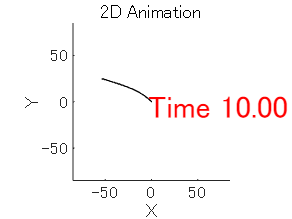

Progress: 0%
Progress: 5%
Progress: 10%
Progress: 15%
Progress: 20%
Progress: 25%
Progress: 30%
Progress: 35%
Progress: 40%
Progress: 45%
Progress: 50%
Progress: 55%
Progress: 60%
Progress: 65%
Progress: 70%
Progress: 75%
Progress: 80%
Progress: 85%
Progress: 90%
Progress: 95%
Progress: 100%



% アニメーションの準備
fig = figure;
hold on;
axis equal;
axis([-1, 1, -1, 1] * 2 * n * sqrt(2)); % 描画範囲
title('2D Animation');
xlabel('X');
ylabel('Y');

% 初期プロットの設定
rectangles = gobjects(n, 1); % 長方形オブジェクトを保存する配列
colors = lines(n); % 色を動的に割り当てる（MATLABのカラーマップ）

% 動的に変数名を生成して対応する値を取得
r = zeros(n, 1); % 半径
l_L = zeros(n, 1); % 左側長さ
l_R = zeros(n, 1); % 右側長さ

for i = 1:n
    % r_i の値を取得
    r_index = find(ismember(valid_values, eval(sprintf('r_%d', i))));
    r(i) = valid_data(r_index);

    % l_L_i の値を取得
    l_L_index = find(ismember(valid_values, eval(sprintf('l_L_%d', i))));
    l_L(i) = valid_data(l_L_index);

    % l_R_i の値を取得
    l_R_index = find(ismember(valid_values, eval(sprintf('l_R_%d', i))));
    l_R(i) = valid_data(l_R_index);
end

for i = 1:n
    % 長辺と短辺を計算
    x_i_side = 2 * r(i);
    y_i_side = l_L(i) + l_R(i);

    % 長方形をプロット
    rectangles(i) = fill([-1, 1, 1, -1] * x_i_side / 2, [-1, -1, 1, 1] * y_i_side / 2, colors(i, :));
end

% 時間を表示するテキスト
time_text = text(-3.5, -5.5, '', 'FontSize', 14, 'Color', 'red');

% 現在の日時を取得してファイル名を設定
current_time = datetime('now', 'Format', 'yyyyMMdd_HHmmss');
video_filename = sprintf('animation_output_%s.mp4', current_time); % 動的なファイル名

% フレームレートの設定と時間ステップの調整
max_frame_rate = 150;
skip_interval = max(1, ceil((1 / dt) / max_frame_rate)); % スキップ間隔を計算
selected_time_indices = 1:skip_interval:length(time_steps); % 選択された時間インデックス
time_steps_reduced = time_steps(selected_time_indices); % 抽出した時間ステップ
actual_frame_rate = min(1 / mean(diff(time_steps_reduced)), max_frame_rate); % 実際のフレームレート

% ビデオライターの設定
v = VideoWriter(video_filename, 'MPEG-4');
v.FrameRate = actual_frame_rate;
open(v);

last_progress_displayed = -1; % 前回表示した進捗率を記録

% アニメーションループ（選択した時間ステップを使用）
for t_idx = 1:length(selected_time_indices)
    time_idx = selected_time_indices(t_idx); % 元の時間インデックス
    for i = 1:n
        % 位置と回転を取得
        x = pos(3 * (i - 1) + 1, time_idx); % x座標
        y = pos(3 * (i - 1) + 2, time_idx); % y座標
        theta = pos(3 * (i - 1) + 3, time_idx); % 回転角度

        % 長辺と短辺を再計算
        x_i_side = 2 * r(i);
        y_i_side = l_L(i) + l_R(i);

        % 長方形のスケーリングされた頂点を定義
        vertices = [-1, 1, 1, -1; -1, -1, 1, 1]; % 単位正方形
        vertices(1, :) = vertices(1, :) * (x_i_side / 2); % 長辺に基づくスケーリング
        vertices(2, :) = vertices(2, :) * (y_i_side / 2); % 短辺に基づくスケーリング

        % 回転行列を適用
        rotated_vertices = rot(theta) * vertices;

        % 平行移動
        final_vertices = rotated_vertices + [x; y];

        % 頂点の更新
        rectangles(i).XData = final_vertices(1, :);
        rectangles(i).YData = final_vertices(2, :);
    end

    % 時間を更新
    time_text.String = sprintf('Time %.2f', time_steps_reduced(t_idx));

    % 描画を更新
    % drawnow;

    % フレームを取得して動画に書き込む
    frame = getframe(fig); % 現在の描画内容をキャプチャ
    writeVideo(v, frame); % 動画ファイルにフレームを書き込む

    % 進捗率を計算
    progress = floor((t_idx / length(selected_time_indices)) * 100); % 進捗率を整数で計算

    % 進捗率が%単位で変化した場合のみ表示
    if mod(progress, 5) == 0 && progress ~= last_progress_displayed
        fprintf('Progress: %d%%\n', progress); % コンソールに進捗率を表示
        last_progress_displayed = progress; % 表示した進捗率を記録
    end
end


% 動画保存を終了
close(v); % 動画ファイルを閉じる

disp(['アニメーションを保存しました: ', video_filename]);

アニメーションを保存しました: animation_output_20241213_010954.mp4



% profile viewer